# **Cam and Crank - Encoder**

This example demonstrates the use of the Cam and Crank Encoder v3 driver blocks. The model is set up to emulate two pairs of one cam and one crank shaft. A fault with a wrong tooth position and duration is emulated for the first cam shaft.

## Setup

### Prerequisites

You require the following to run this example:

- Speedgoat real-time target machine with one configurable I/O module from the IO3xx family

- A Speedgoat configuration file that supports **2 x Cam & Crank Encoder v3 channels (CRE) **and** 4 x General Purpose Digital Input channels (DIO)**

- Connector cable from the I/O module to the terminal board

- Terminal board

### Test Setup

In this example, two pairs of Cam and Crank signals are generated based on the Cam and Crank Encoder v3 driver blocks. The four output signals are wired to general purpose digital inputs on the terminal board for logging and visualization of the generated wave form.

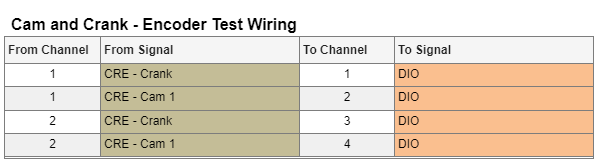

If DIO channels 1 to 4 share the same I/O pins as the CRE channels with your configuration file, you may use different DIO channel numbers than indicated above. Make sure to adapt the DIO channel vector in the Digital Input driver block accordingly.

## Initialize and Open the Simulink Model

 
% Open Simulink model
modelName = 'sgMdl_IO3xx_CamCrank_Encoder';
open_system(modelName);

Before the Simulink model can be built, the I/O module and configuration file must be specified in the IO3xx Setup block, as this example can be executed on different configurable I/O modules. First, open the mask of the IO3xx Setup block and select your I/O module from the drop-down. Once the mask has extended, select the configuration file that supports the required functionalities.

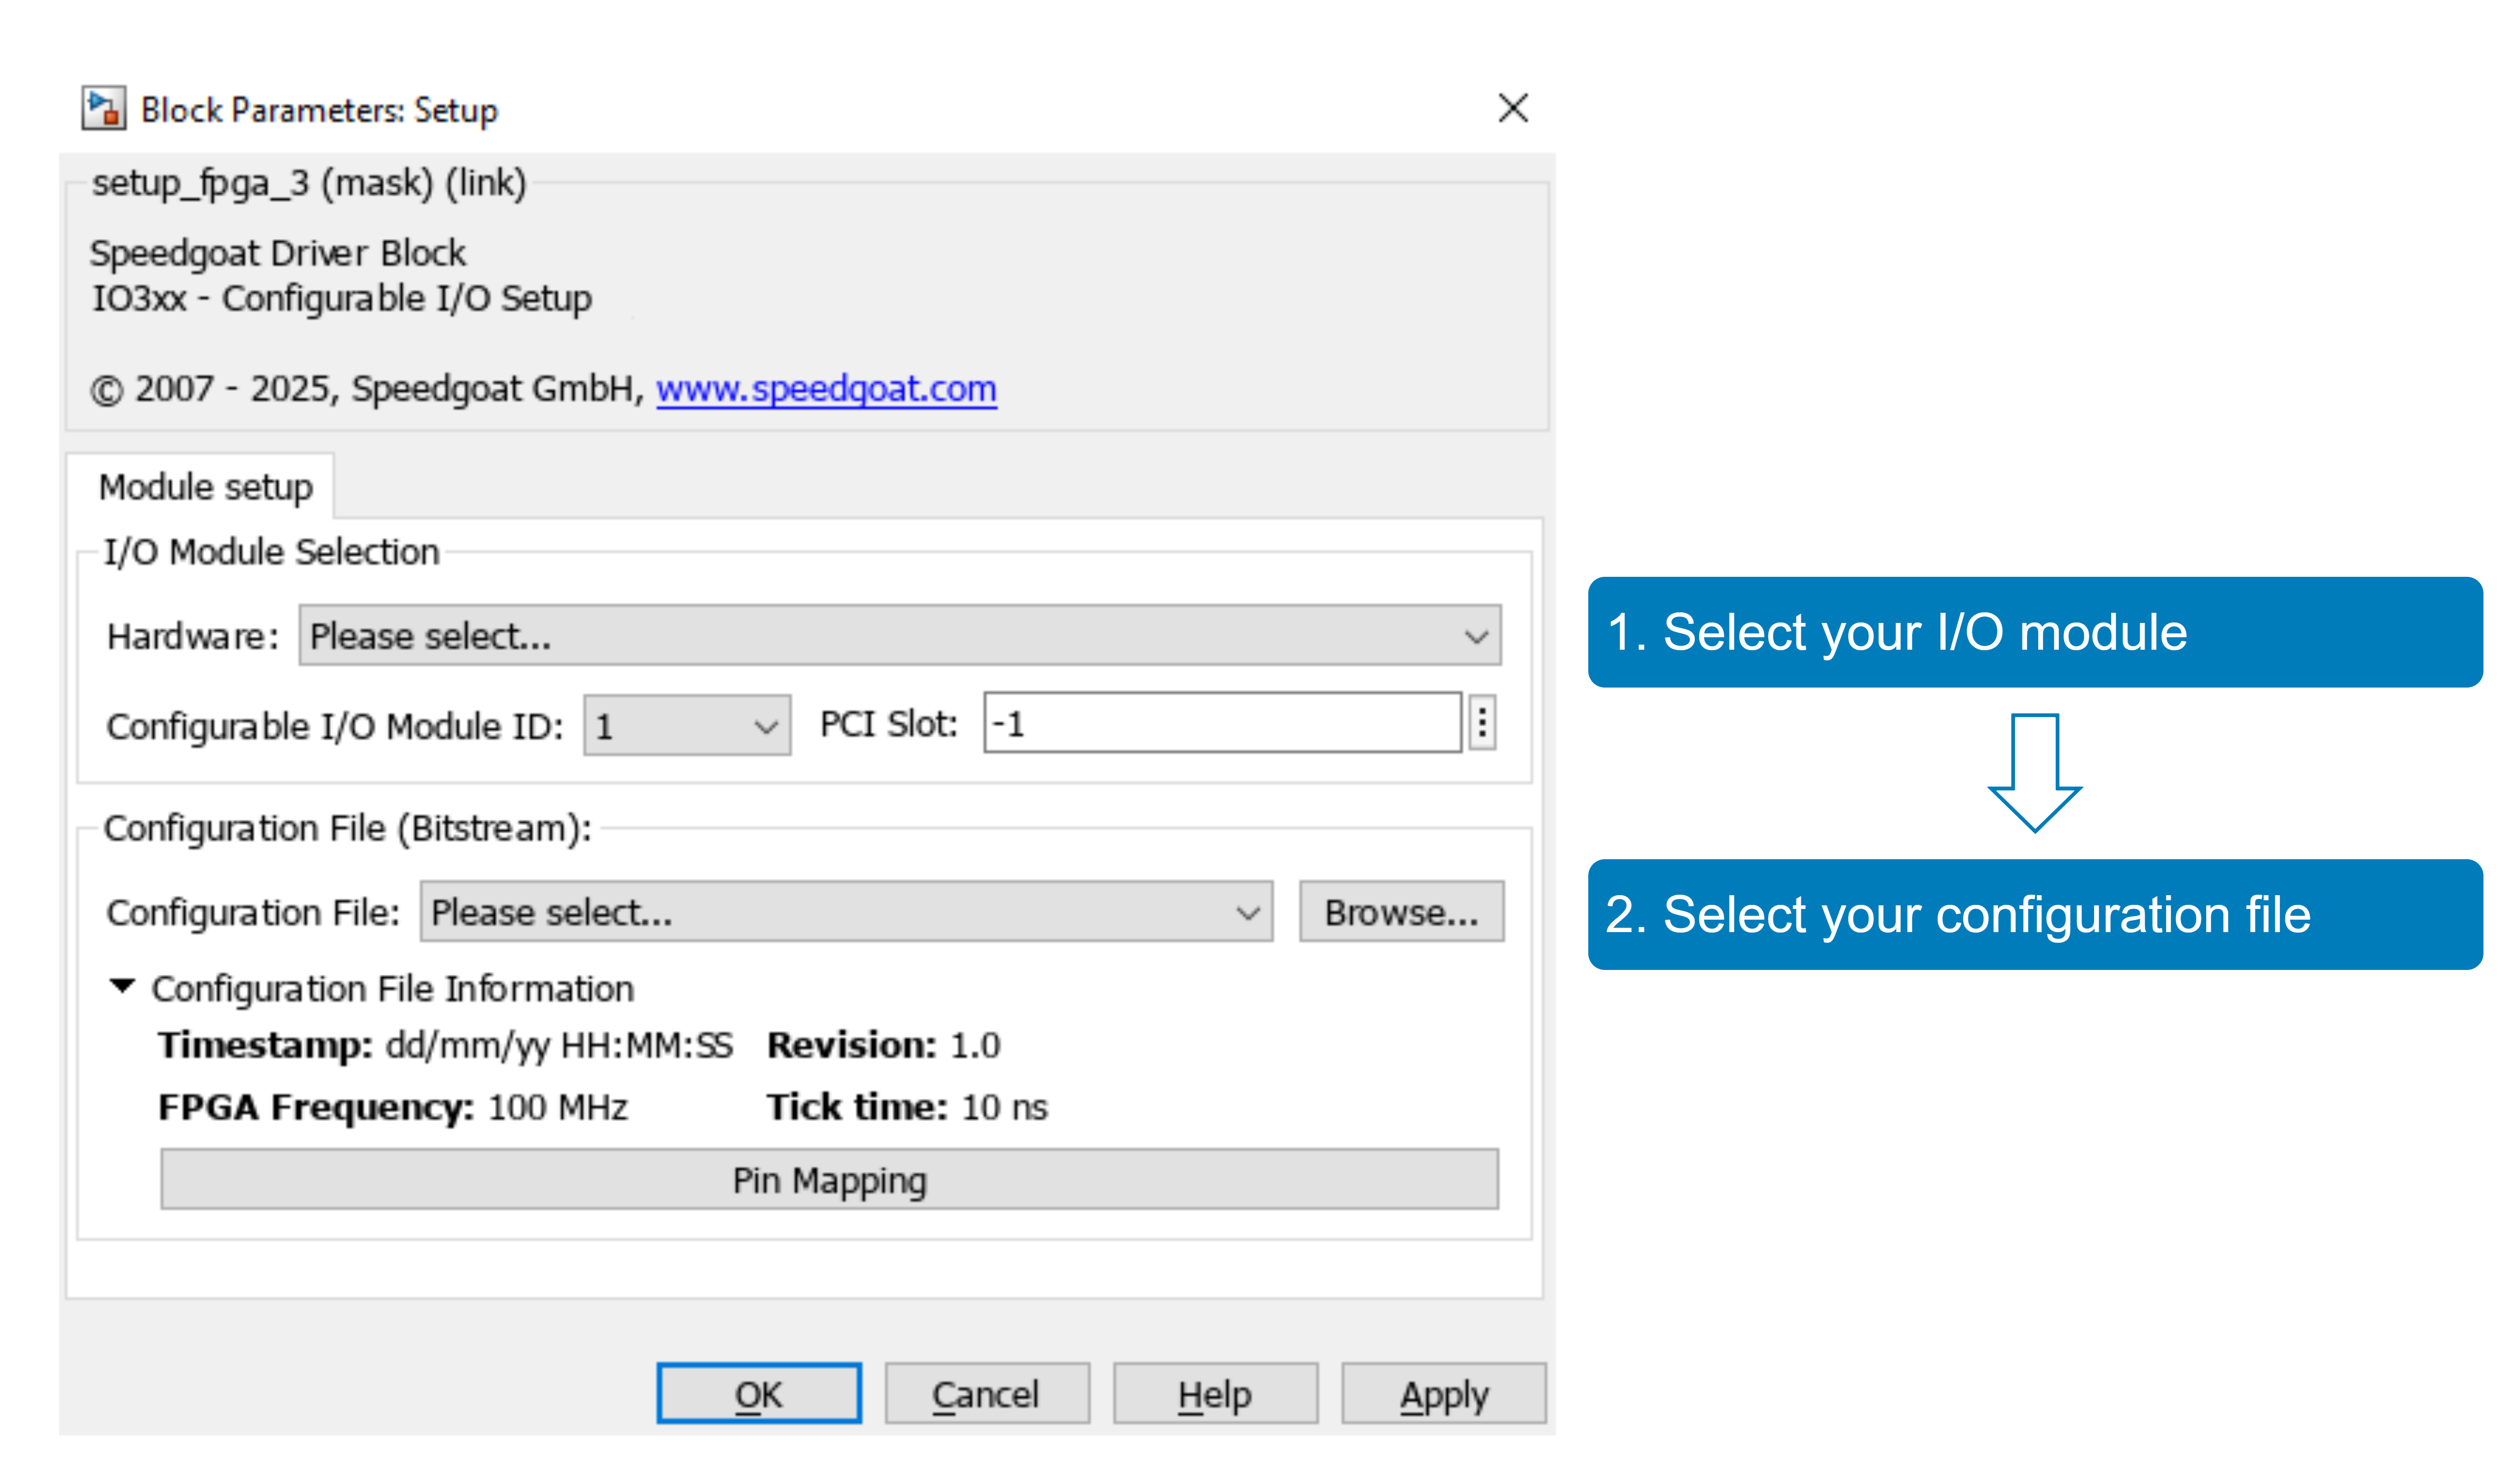

With the **Pin Mapping** button you can now check where the functionalities are located.

This model uses a sample time of 100 us.

## Model Description 

### Crank Encoder

Two independent Crank shafts are emulated. Both shafts have a total of 30 crank teeth of which two are missing. These values are defined by the **Number of crank teeth vector** and **Number of missing crank teeth vector** in the **Crank generation** tab of the block mask. The shaft speed is 0 rpm at model start as defined by the **Initial Speed (rpm) vector** in the **Crank generation** tab of the block mask. During model execution, the shaft speed is defined by the **Speed** input of the block [rpm]. The module integrates the angular velocity to obtain the shaft position with a high resolution on the FPGA. The position is fed back into the Simulink model through the **Position** output of the block. The position is between 0 and 720 degrees to cover one engine cycle. In this model, both Crank shafts accelerate to a speed of 600 and 1200 rpm respectively. After the acceleration period the speed remain constant or both channels.

### Cam Encoder

The position and length of the cam teeth can be defined with the **Cam Encoder (3)** driver block. Each crank channel shares the high-resolution position signal with the corresponding cam channel. This is a permanent connection between the two modules within the FPGA. Refer to the pin mapping of your configuration file to learn which cam channels are connected to which crank channels. Multiple cam channels may be linked to a single crank channel.

The driver block supports up to 10 cam teeth. The tooth position and length is defined by the **Start** and **Length** input ports of the block and can be changed during the Simulation. These ports must be enabled in the I**nput and output ports configuration** tab of the block mask. The inputs expect a column vector with a fix length of 10 elements per active channel. Each element defines the start angle [degree] and length [degree] of the corresponding tooth.

The example model is set up for two cam shafts with 4 teeth each. A faulty tooth is simulated on the first channel after 5 seconds of simulation time. The **Step** and **Switch** blocks are used to change the **Start** and **Length** input vector.

Note that the **Start** and **Length** inputs can be disabled. In this case, the cam shaft will have a constant tooth pattern throughout the entire simulation. It is defined by the **Initial Cam start matrix** and **Initial Cam length matrix** parameters in the **Cam Encoder** tab of the block mask.

**Digital Input**

The digital input block is used to capture the waveform of the generated signals and visualize them in the Simulation Data Inspector (SDI). For this purpose, all four cam and crank signals must be wired to a digital input pin on the terminal board.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model. Create the real-time application file
% (.mldatx).
slbuild(modelName);    

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName); 

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode',   'external')   % put model into External Mode
set_param(modelName,'SimulationCommand','connect')    % connect with External Mode  

% Start the real-time application
tg.start;

### Display Speed and Position

 
% Clear and set up the SDI view
Simulink.sdi.clearAllSubPlots
Simulink.sdi.setSubPlotLayout(2,1);

% Get the last run
allIDs = Simulink.sdi.getAllRunIDs;
lastRunID = allIDs(end);
lastRun = Simulink.sdi.getRun(lastRunID);

% Get the speed and position signals of both crank channels
Speed = lastRun.getSignalsByName('SPEED');
Position = lastRun.getSignalsByName('CRANK_POSITION');

% Display the speed and position of both crank channels
plotOnSubPlot(Speed.Children(1),1,1,true);
plotOnSubPlot(Speed.Children(2),1,1,true);
plotOnSubPlot(Position.Children(1),2,1,true);
plotOnSubPlot(Position.Children(2),2,1,true);

% Set time range to see acceleration sequence between 0 and 2 seconds
Simulink.sdi.setSubplotLimits(1,1,'tRange',[0,2]);

% View SDI
Simulink.sdi.view;

Both crank shafts accelerate for one second to 600 rpm and 1200 rpm respectively. 

### 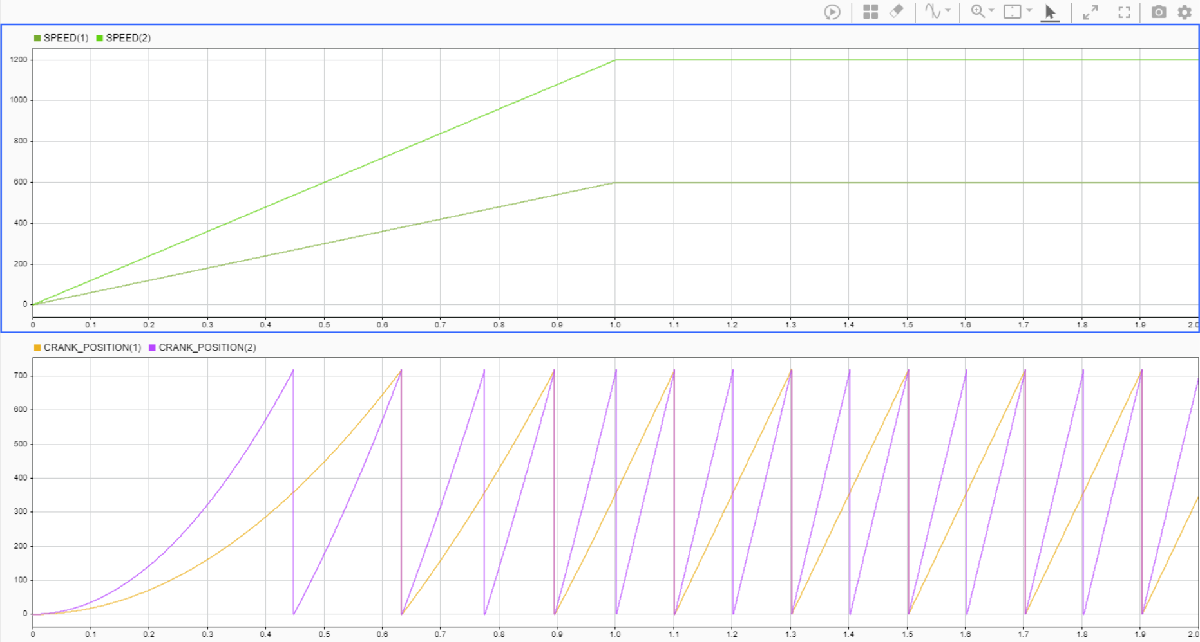

### Display Cam and Crank signals

 
% Clear and set up the SDI view 
Simulink.sdi.clearAllSubPlots
Simulink.sdi.setSubPlotLayout(4,1);

% Get the speed and position signals of both crank channels
Crank1 = lastRun.getSignalsByName('DI_CRANK1');
Cam1 = lastRun.getSignalsByName('DI_CAM1');
Crank2 = lastRun.getSignalsByName('DI_CRANK2');
Cam2 = lastRun.getSignalsByName('DI_CAM2');

% Display the speed and position of both crank channels
plotOnSubPlot(Crank1,1,1,true);
plotOnSubPlot(Cam1,2,1,true);
plotOnSubPlot(Crank2,3,1,true);
plotOnSubPlot(Cam2,4,1,true);

% Set time range to see the faulty cam tooth after 5 seconds
Simulink.sdi.setSubplotLimits(1,1,'tRange',[4.9,5.3]);

% View SDI
Simulink.sdi.view;

The digital inputs are used to capture and visualize the cam and crank signal. Alternatively, you can measure the wave forms with an oscilloscope.

The crank signals indicate that the second channel turns twice as fast. The fault of the first cam signal occurs after five seconds. The start position of the second tooth is changed from 180 to 230 degree and its length from 60 to 20 degrees (compare green and red circles).

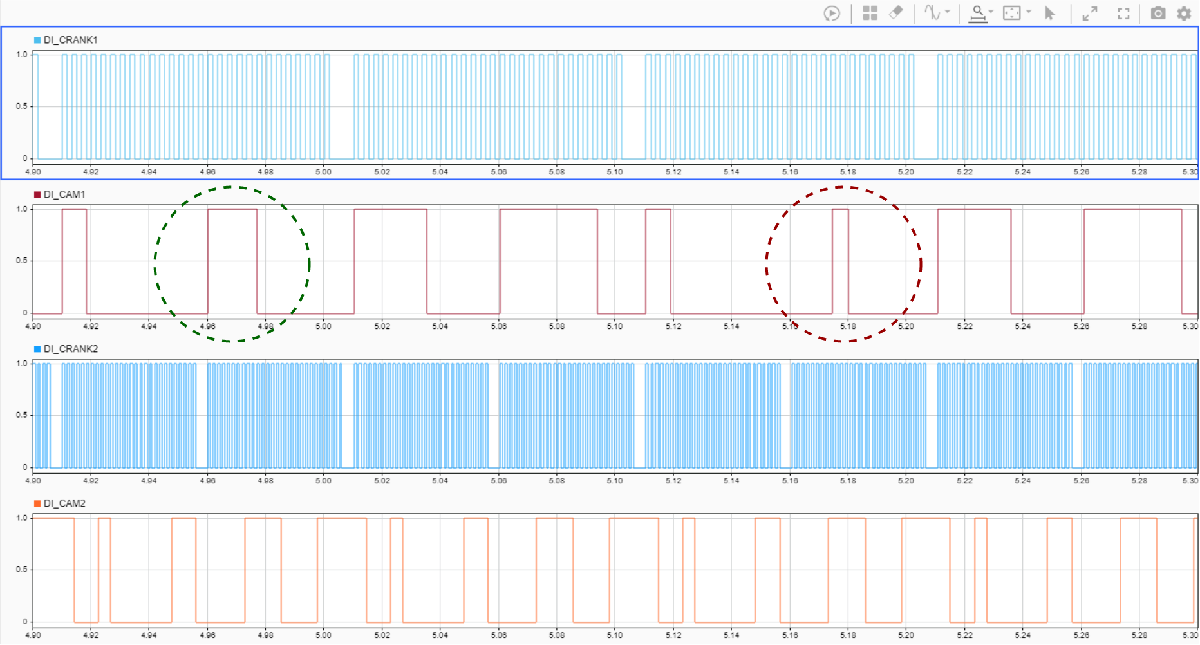

## Additional References

- [Cam and Crank documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_cam_and_crank)